figure
%原始数据
x = [10 20 30 40 50 60 70 80 90 100]

x =     10    20    30    40    50    60    70    80    90   100


y = [104.0 107.9 111.7 115.6 119.6 123.4 127.4 131.1 135.1 138.5]

y =   104.0000  107.9000  111.7000  115.6000  119.6000  123.4000  127.4000  131.1000  135.1000  138.5000


% 使用polyfit进行线性拟合，阶数为1
a=polyfit(x,y,1)

a =     0.3861  100.1933


% 生成新的数据点
xi = 0:10:100;
yi = polyval(a,xi)

yi =   100.1933  104.0545  107.9158  111.7770  115.6382  119.4994  123.3606  127.2218  131.0830  134.9442  138.8055


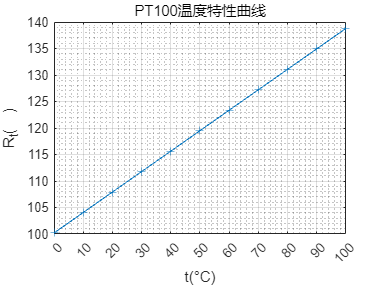

%绘图
plot(xi,yi,Marker="+");
title('PT100温度特性曲线')
xlabel('t(\circC)')
ylabel('R_{t}(  )')
xticks(0:10:100)
yticks(100:5:150)
grid on;
grid minor;


% 计算相关系数矩阵
corr_matrix = corrcoef(x, y);

% 获取相关系数（Pearson相关系数）
correlation_coefficient = corr_matrix(1, 2);

% 计算R方值
r_squared = correlation_coefficient^2;

disp(['相关系数 (r)：', num2str(correlation_coefficient)]);

相关系数 (r)：0.99993


disp(['R方值 (r^2)：', num2str(r_squared)]);

R方值 (r^2)：0.99986
